# Map Building Laser Based

**Grup 11-H:**

**Estudiants: **

**    - Pol Casacuberta Gil**

**    - Marta Granero I Martí**

**Link: **[https://drive.matlab.com/sharing/b8a7f88a-dcb6-4c09-a328-ba6c7e737807](https://drive.matlab.com/sharing/b8a7f88a-dcb6-4c09-a328-ba6c7e737807)

clear
clf
load ("Sensor_Data.mat")

## **Robot parameters**

d_lr = 0.6

d_lr = 0.6000

S = 0.26

S = 0.2600

r = 0.1

r = 0.1000

Ts = 0.02 %Ts=0.02 r and l

Ts = 0.0200

NR = 100 %gear_ratio

NR = 100


L_inc = left_angular_speed(:,2)*r*Ts/NR

L_inc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


R_inc = right_angular_speed(:,2)*r*Ts/NR

R_inc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



delta_d=(R_inc+L_inc)/2

delta_d =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


delta_t=(R_inc-L_inc)/(2*S)

delta_t =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## **Trajectory Calculation**

Robot_pose=transl(0,0,0)*trotz(-pi/2) %posicio inicial del robot

Robot_pose =      0     1     0     0
    -1     0     0     0
     0     0     1     0
     0     0     0     1


Pose(:,:,1)=Robot_pose;
for i=1:length(L_inc)-1
    Pose(:,:,i+1)=Pose(:,:,i)*transl(delta_d(i),0,0)*trotz(delta_t(i));
    Position(:,i+1)=transl(Pose(:,:,i));
    Orientation(:,i+1)=tr2rpy(Pose(:,:,i));
end

## **Plotting trajectory**

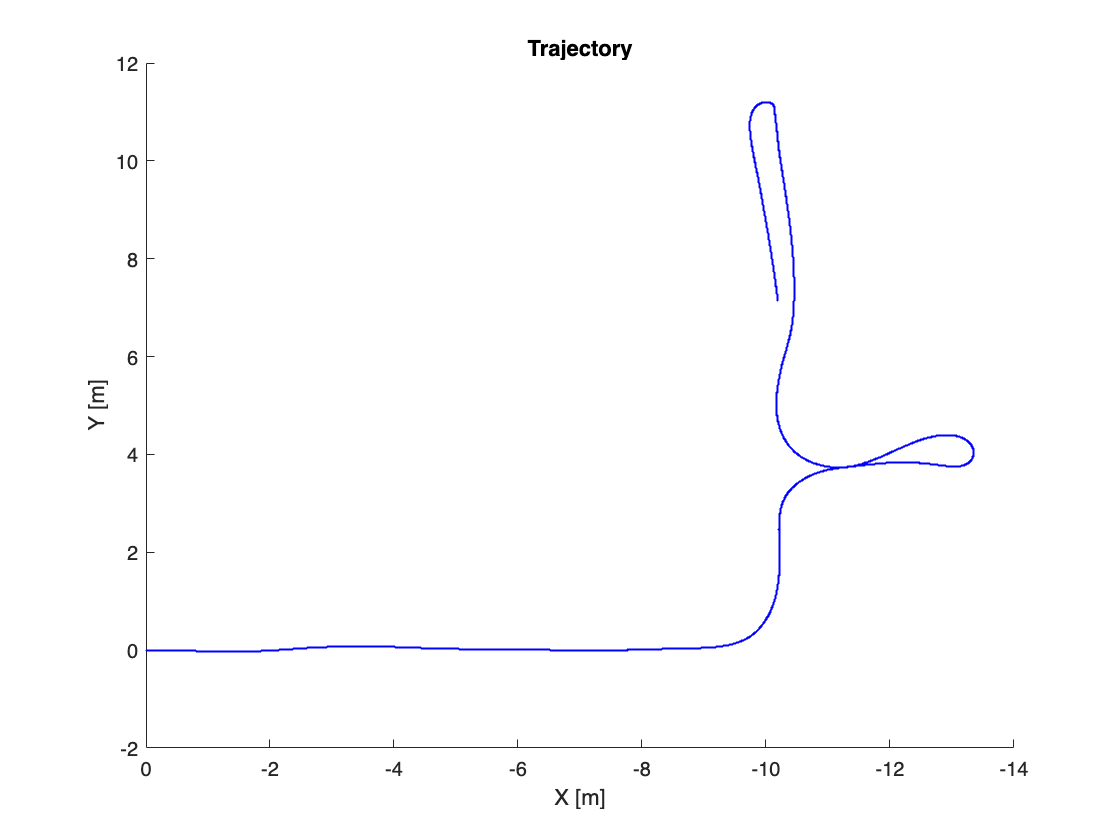

figure
hold on
plot(Position(1,2:end),Position(2,2:end),'b.','MarkerSize',1)
view(-90,90)
title('Trajectory')
ylabel('X [m]')
xlabel('Y [m]')

## **Building the Map**

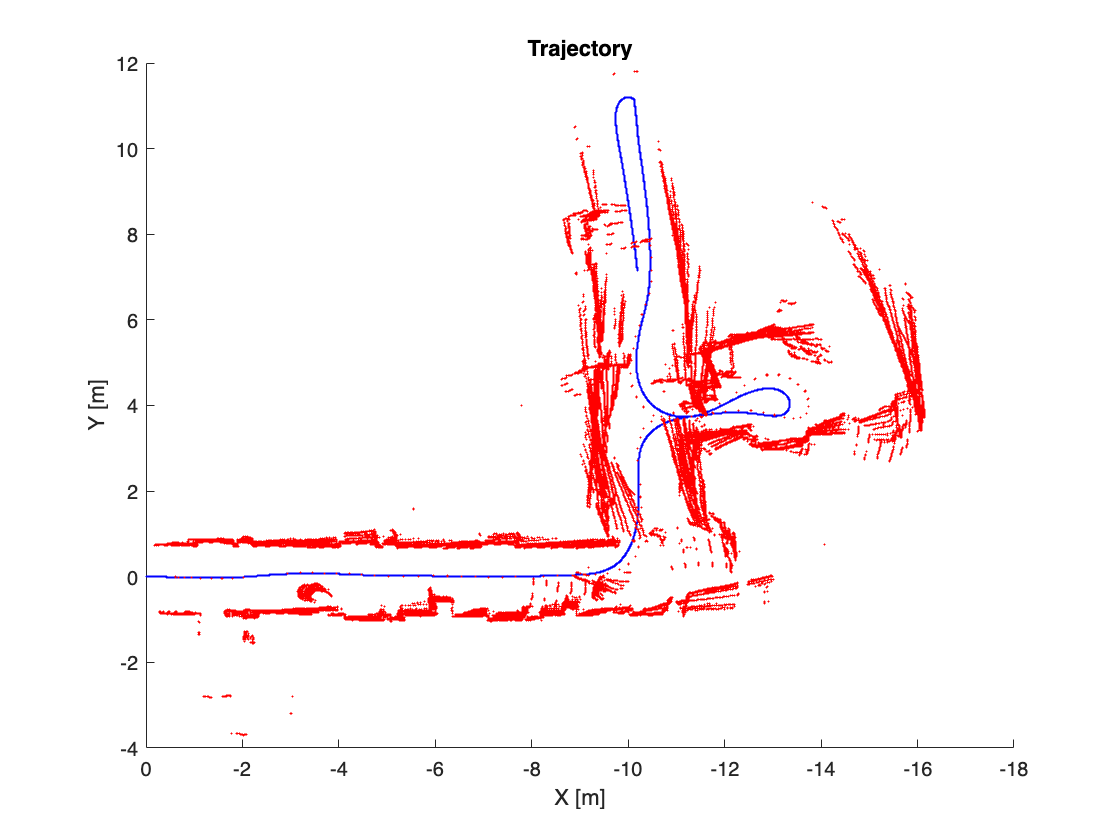

ang_laser=linspace(-120*pi/180,120*pi/180,682);

for i=1:1
    %coordenades polars -> cartesianes amb pol2cart
    [x y] = pol2cart(ang_laser, polar_laser_data(i,2:683)/1000); %estava en mm
    pointsL = [x; y; zeros(1,682); ones(1,682)];
    for j=1:682
        if(pointsL(1,j) ~= 0 || pointsL(2,j) ~= 0)
            pointsR = transl(d_lr,0,0)*pointsL(:,j);
            %polar_laser_data -> Ts=0.4; left/right w speed -> Ts=0.02
            pointsU = Pose(:,:,i*(0.4/0.02))*pointsR;
            plot(pointsU(1),pointsU(2),'r.','MarkerSize',1)
            %view(-90,90)
        end
    end
end

% hold off